## **Simulation for Active Structures -- A Living Textbook**

**by Yi Zhu (PhD)**

clear all; 
close all; 
clc;

***Please add "00_SourceCode_Elements" and "00_SourceCode_Solver" into path before running the code***

### **Section 06 - Stiffness Matrix Assembly**

**6.1 If I have two springs, what should I do now?**

The problem we want to tackle here is - how to capture a system with multiple bars? We can salvage the code we previously did for the local force calculation and the local stiffness calculation for a single bar, but we will learn how to assembly the global force vector and the global stiffness matrix here. With out loss of generality, let's take a look at the following two bar (truss) system shown below.   

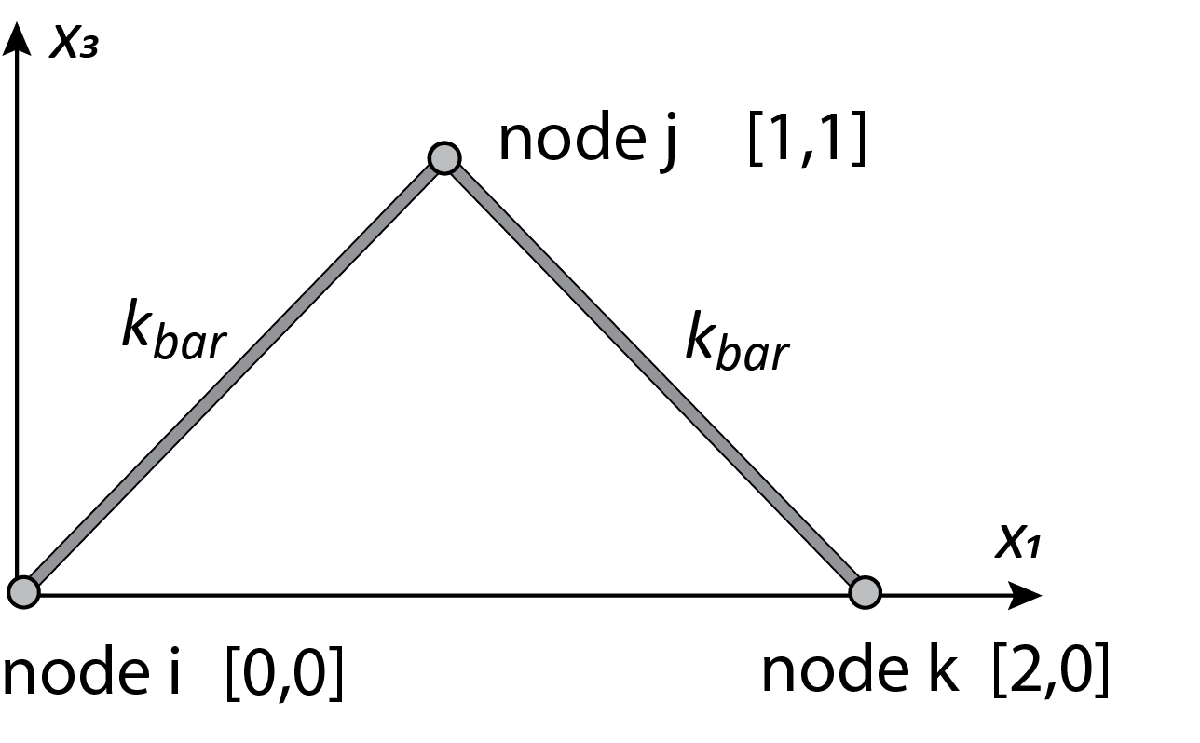

we can initiate the system using the following code:

% the nodal coordinates
% please note that the x2 (y) direction is zero for all three nodes
X_i=[0,0,0];
X_j=[1,0,1]; 
X_k=[2,0,0];
% The material constant is
E=1;
A=1;
L0=sqrt(2)

L0 = 1.4142

kbar=E*A/L0;
% Establish bar element
bar=CD_Elements_Bars;

Now, assuming that the j-th node is moved up by 0.01, we can compute the bar force from each bar as the following:

% deformed nodal coordinate
x_j=[1,0,1+0.01];
% Compute forces from bar 1
bar_force_1=bar.Solve_Local_Force(X_i,x_j,L0,E,A)

bar_force_1 =    -0.0035
         0
   -0.0036
    0.0035
         0
    0.0036


% Compute forces from bar 2
bar_force_2=bar.Solve_Local_Force(x_j,X_k,L0,E,A)

bar_force_2 =    -0.0035
         0
    0.0036
    0.0035
         0
   -0.0036


Ok cool, we can find the internal force from each element nice and easy. 

Let's next take some time to discuss what is a global force vector and a global stiffness matrix at the first place. We shall start by counting the degrees-of-freedom in the system - we have three nodes so we should have a total of 9 degrees-of-freedom in terms of mechanics. Therefore, the global force vector will be a 9 by 1 vector while the global stiffness matrix will be a 9 by 9 matrix. 

The global stiffness matrix and force vector are needed to run simulation for the full system. Let's first take a look at the force vector, each of the bar will gives us a 6 by 1 vector so our task now is to assemble the two 6 by 1 vector into the global force vector which is 9 by 1. This process is illustrated using the following figure:

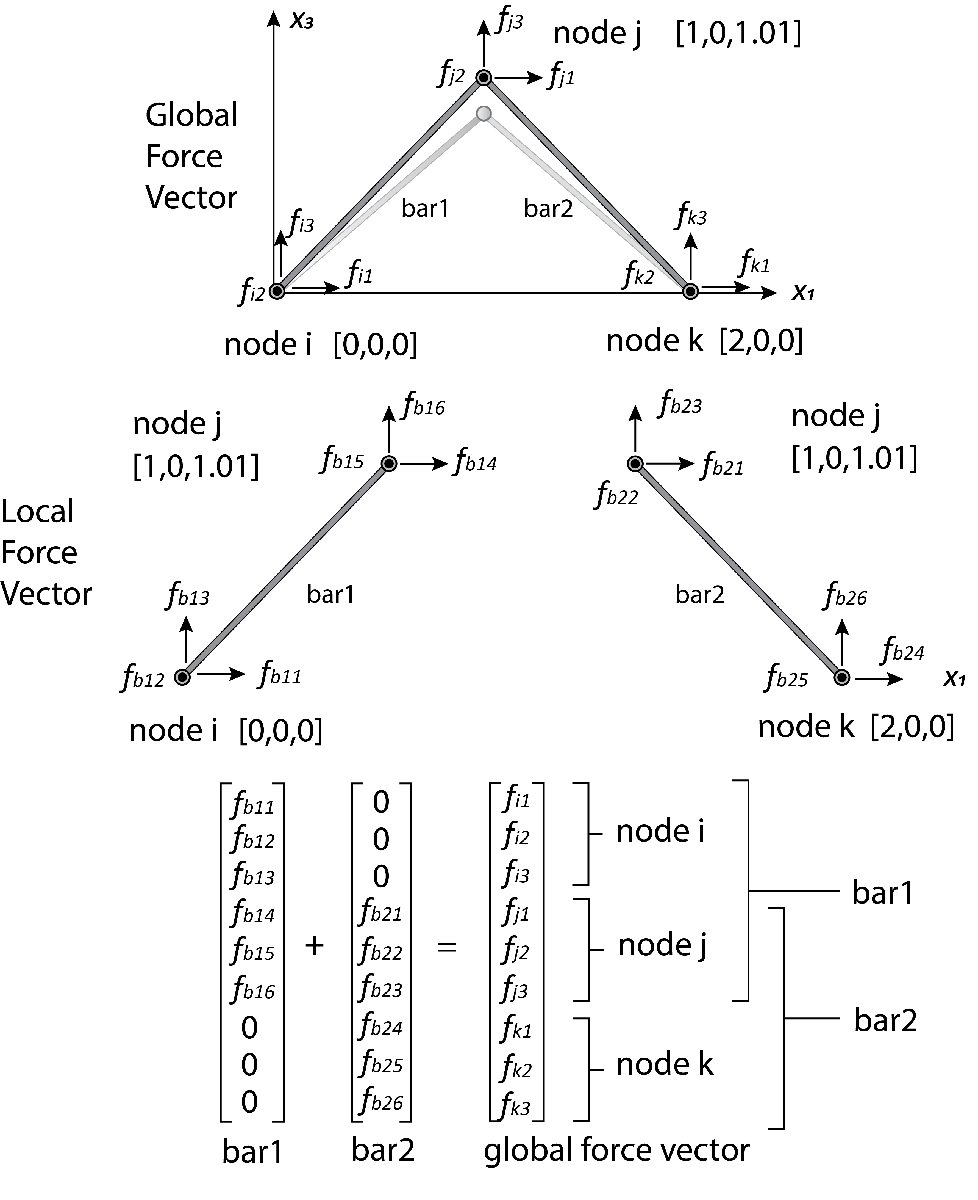

Here, the golobal force vector is 9 by 1 because it is corresponding to 3 nodes. With our convention, node i is row 1 to row 3, node j is row 4 to row 6, and node k is row 7 to row 9. The local force vector for bar 1 is 6 by 1 where row 1 to row 3 is correlated to node i and row 4 to row 6 is correlated to node j. Therefore, we can place the local force vector from bar 1 to the global force matrix for row 1 to row 6 so that the nodes match out. Similarly, we do the same thing for bar 2. The one item to pay attention to here is that, we need to add the stiffness when bars are sharing one node. For example, for node j, the force vector is:


$$f_{\textrm{j1}} =f_{\textrm{b14}} +f_{\textrm{b21}}$$



$$f_{\textrm{j2}} =f_{\textrm{b15}} +f_{\textrm{b22}}$$



$$f_{\textrm{j3}} =f_{\textrm{b16}} +f_{\textrm{b23}}$$


This process can be represented using the following code:

% initialize global force vector
global_force=zeros(9,1);
global_force(1:3)=bar_force_1(1:3);
global_force(4:6)=bar_force_1(4:6)+bar_force_2(1:3);
global_force(7:9)=bar_force_2(4:6);
global_force

global_force =    -0.0035
         0
   -0.0036
    0.0000
         0
    0.0071
    0.0035
         0
   -0.0036


Usually, this is done using the for loop to loop through every elements in the system. Interested readers can refer to the source code to see how this is done in Sim-FAST. Here, to compare, we will get the results from the stock simulator. To do this, we will need to use another class callded "Elements_Nodes". This class is used to store the nodal coordinates and the deformation of each nodes. 

% create the node object
node=Elements_Nodes;
node.coordinates_mat=[X_i;X_j;X_k];
% Define deformation
node.current_U_mat=zeros(3,3);
node.current_U_mat(2,3)=0.01;

% Define the bars
bar.node_ij_mat=[1,2;2,3];
% first bar connects node 1 and node 2 
% second bar connects node 3 and node 4

% Define areas and Young's modulus
bar.A_vec=[A;A];
bar.E_vec=[E;E];

% Initialize the bar
bar.Initialize(node);

% Solve the global force
global_force_stock=bar.Solve_Global_Force(node,node.current_U_mat);
global_force_stock

global_force_stock =    -0.0035
         0
   -0.0036
    0.0000
         0
    0.0071
    0.0035
         0
   -0.0036


This result is identical with the code we wrote previously. After defining how the bars are connected and setting up the properties, the stock class function is capable to solve the global force for us directly. 

**6.2 Stiffness Matrix Assembly**

Now that we knows how to do the global assembly of force vector, let's start working on the golobal stiffness matrix. The principle is almost identical except that we now need to work on the 2 dimensional stiffness matrix. The overall process is explained in the following figure. 

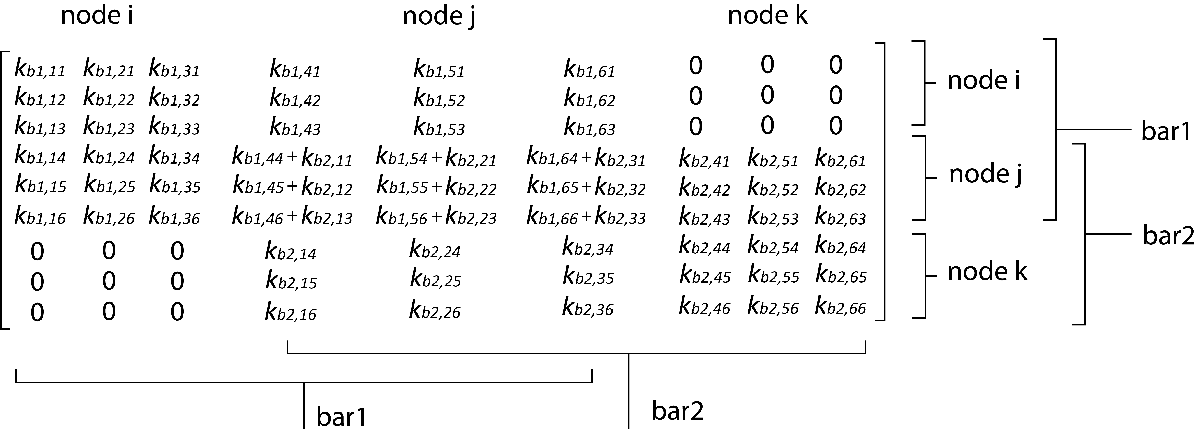

The way we can look at this 9 by 9 matrix is to break it into 3 by 3 components. For instance, the [4:6,1:3] is related the forces acting on node i when node j is infinitesimally perturbed. The forces and stiffness generated in this block is a sole contribution from bar 1. Similarly, the middle [4:6,4:6] stiffnes is the correlated to the forces acting on node j, when node j itself is infinitesimally perturbed. This block of stiffness matrix sees contribution from both bar 2 and bar 2 as both bars are connected at node j. The block [7:9,1:3] is a zero matrix because node i and node k is not connected - no force will be generated at node i if node k is moved. 

This matrix assembly process can be done using the following code. Again, we will salvage the local stiffness calculation code from the previous section through using the stock element. 

% Compute stiffness matrix from bar 1
bar_stiff_1=bar.Solve_Local_Stiff(X_i,x_j,L0,E,A)

bar_stiff_1 =     0.3500         0    0.3507   -0.3500         0   -0.3507
         0         0         0         0         0         0
    0.3507         0    0.3571   -0.3507         0   -0.3543
   -0.3500         0   -0.3507    0.3500         0    0.3507
         0         0         0         0         0         0
   -0.3507         0   -0.3543    0.3507         0    0.3543


% Compute stiffness matrix from bar 2
bar_stiff_2=bar.Solve_Local_Stiff(x_j,X_k,L0,E,A)

bar_stiff_2 =     0.3500         0   -0.3535   -0.3500         0    0.3535
         0         0         0         0         0         0
   -0.3535         0    0.3543    0.3535         0   -0.3543
   -0.3500         0    0.3535    0.3500         0   -0.3535
         0         0         0         0         0         0
    0.3535         0   -0.3543   -0.3535         0    0.3571


The way we can combine the above two matrix is shown as the following. The code is written using for loop, which is very common in actual FEM simulation pacakges. For coding simulation in a high-level language like MATLAB or Python, writting a for like this is not ideal for computational speed - which is why vectorized versions are used. In the source code package, most of the elements do have vectorized version and the naming start with "Vec" not "CD". We will not worry about vectorization for now unless wrting a for loop like what we have below is a piece of cake for you. 

% Store the local stiffness matrix in 3-dim tensor
bar_stiff=zeros(2,6,6);
bar_stiff(1,:,:) = bar_stiff_1;
bar_stiff(2,:,:) = bar_stiff_2;
% This matrix stores how bar is connected to the nodes
bar_node=[1,2;2,3];

% initialize global force vector
global_stiff=zeros(9,9);
for element_num=1:2
    for i=1:2
        for j=1:2
            n1=bar_node(element_num,i);
            n2=bar_node(element_num,j);
            global_stiff(3*(n1-1)+1:3*n1,3*(n2-1)+1:3*n2)=...
                global_stiff(3*(n1-1)+1:3*n1,3*(n2-1)+1:3*n2)+...
                squeeze(bar_stiff(element_num,3*i-2:3*i,3*j-2:3*j));
            % Please note that we need to use squeeze to cancel out
            % additional dimensions in 3D matrix. 
        end    
    end
end
global_stiff

global_stiff =     0.3500         0    0.3507   -0.3500         0   -0.3507         0         0         0
         0         0         0         0         0         0         0         0         0
    0.3507         0    0.3571   -0.3507         0   -0.3543         0         0         0
   -0.3500         0   -0.3507    0.7001         0   -0.0028   -0.3500         0    0.3535
         0         0         0         0         0         0         0         0         0
   -0.3507         0   -0.3543   -0.0028         0    0.7085    0.3535         0   -0.3543
         0         0         0   -0.3500         0    0.3535    0.3500         0   -0.3535
         0         0         0         0         0         0         0         0         0
         0         0         0    0.3535         0   -0.3543   -0.3535         0    0.3571


Let's compare this with what we can get from the stock function:

% Solve the global force
global_stiff_stock=bar.Solve_Global_Stiff(node,node.current_U_mat);
global_stiff_stock

global_stiff_stock =     0.3500         0    0.3507   -0.3500         0   -0.3507         0         0         0
         0         0         0         0         0         0         0         0         0
    0.3507         0    0.3571   -0.3507         0   -0.3543         0         0         0
   -0.3500         0   -0.3507    0.7001         0   -0.0028   -0.3500         0    0.3535
         0         0         0         0         0         0         0         0         0
   -0.3507         0   -0.3543   -0.0028         0    0.7085    0.3535         0   -0.3543
         0         0         0   -0.3500         0    0.3535    0.3500         0   -0.3535
         0         0         0         0         0         0         0         0         0
         0         0         0    0.3535         0   -0.3543   -0.3535         0    0.3571


The out put from our derived code looks identical to the stock function in the Sim-FAST pacakge. This is good, indicating that we had done our job nicely. 

**6.3 Automate the Process for Many Bars - Force Assembly**

Typically, we will need more bars to make a real structure. In this case, we will want to create a code to achieve the force vector and the stiffness matrix assembly. Let's try to understand how we can automate this process here with the help of the following structure. 

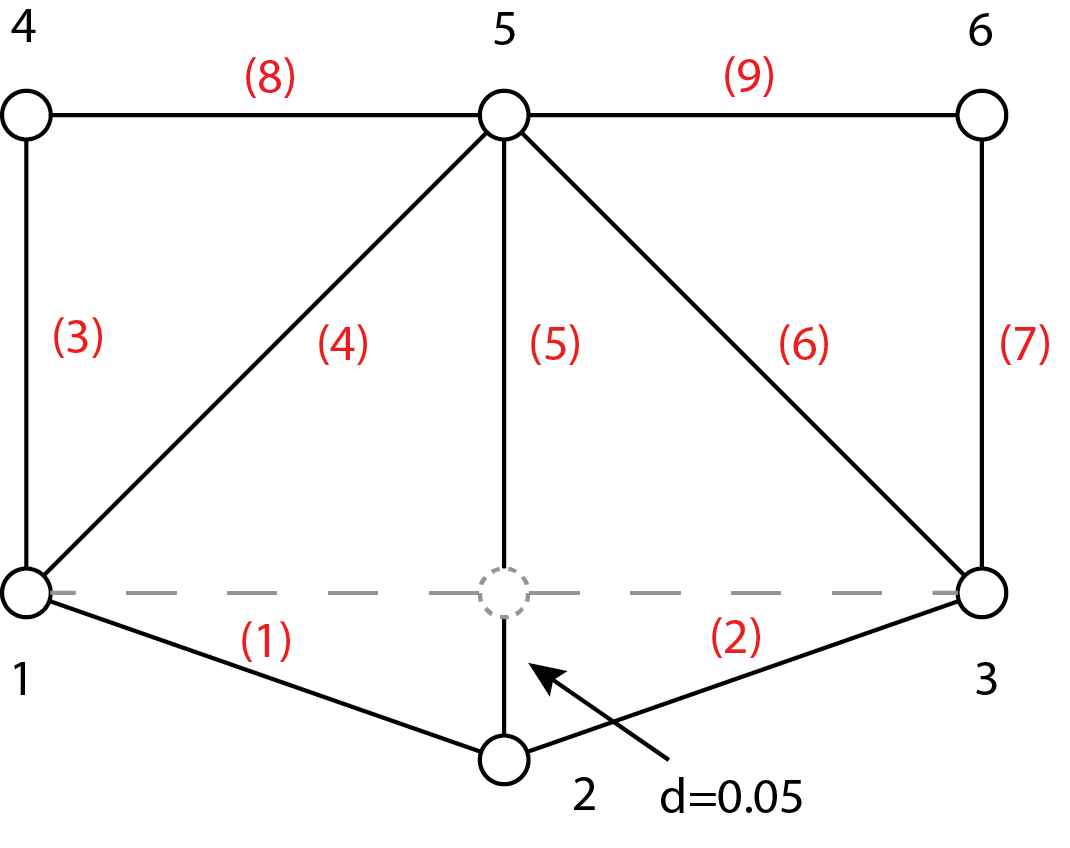

Let's see how we want to set up the input for this system. Most likely, we have a matrix storing the nodal coordinates. This can look like this:

% Nodal coordinate matrix of the above structure
nodal_coordinates=[0 0 0;
                   1 0 0;
                   2 0 0;
                   0 0 1;
                   1 0 1;
                   2 0 1];

% Find the deformed nodal coordinates
deformed_coordinates=nodal_coordinates;
deformed_coordinates(2,3)=deformed_coordinates(2,3)-0.05;

Next, we can code another matrix to represents how the bars are connected.

% This matrix defines how bars are connected
bar_connection=[1 2;
                2 3;
                1 4;
                1 5;
                2 5;
                3 5;
                3 6;
                4 5;
                5 6;];
% This vector stores the lengths of the bars
bar_L0=[1 1 1 sqrt(2) 1 sqrt(2) 1 1 1];

Here, let's code a for loop to acheive the assembly process. First, we find the total number of bars and nodes.  

% Automatically calculate the number of nodes
nodeNum=size(nodal_coordinates);
nodeNum=nodeNum(1);

% Automatically calculate the number of bars
barNum=size(bar_connection);
barNum=barNum(1);

Next, we initialize the global force vector

% Initialize the global force vector
global_force=zeros(nodeNum*3,1);

The following code use a for loop to loop trhough all the bars. We find the reaction force from each bar, and then sum them into the appropriate location of the global force vector based on how the bars are connected. 

% Loop through all bars, calculate the local force
% Then add the local force to the global force vector
for i=1:barNum
    
    xi=deformed_coordinates(bar_connection(i,1),:);
    xj=deformed_coordinates(bar_connection(i,2),:);

    nodei=bar_connection(i,1);
    nodej=bar_connection(i,2);

    localF = bar.Solve_Local_Force(xi,xj,bar_L0(i),E,A);

    % The first node of the selected bar
    global_force((3*nodei-2):(3*nodei))=...
        global_force((3*nodei-2):(3*nodei))+...
        localF(1:3);

    % The second node of the selected bar
    global_force((3*nodej-2):(3*nodej))=...
        global_force((3*nodej-2):(3*nodej))+...
        localF(4:6);

end

global_force

global_force =    -0.0012
         0
    0.0001
         0
         0
   -0.0501
    0.0012
         0
    0.0001
    0.0000


Let's see if this above code actually gives us the right answer. To do that, let's check if stock function gives out the similar results. 

% Reset the node 
node.coordinates_mat=nodal_coordinates;
% deformation matrix
U_mat = deformed_coordinates - nodal_coordinates;

% Set up the bar
bar.node_ij_mat = bar_connection;
bar.A_vec=ones(9,1);
bar.E_vec=ones(9,1);
bar.L0_vec=bar_L0';

% Solve the forces
[global_force_from_stcok,K]=bar.Solve_FK(node,U_mat);

% compare two force
global_force_from_stcok-global_force

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


OK, we get a zero vector! This tells us that the code we created in this file solves the exact results as the stock bar element. Thus, what we created is correct!. In fact, if we open the function in the source code, we will see that the "Solve_Global_Force" function in the bar use the exact formulation to toop through all bar elements and then assembles the global force vector. Finally, let's try to plot the solution to get an idea what internal forces are created:

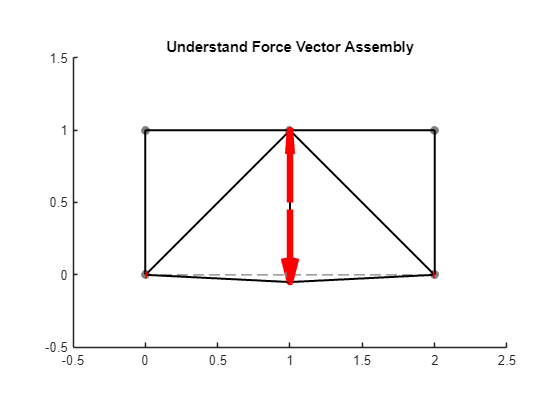

% Plot the figgure
figure
hold on
title('Understand Force Vector Assembly')
view(0,0); 
set(gca,'DataAspectRatio',[1 1 1])
axis([-0.5,2.5,-1,1,-0.5,1.5])

% We first plot the deformed bar and the original bar
% This is the original bar location
for i=1:barNum
    plot3([nodal_coordinates(bar_connection(i,1),1),...
           nodal_coordinates(bar_connection(i,2),1)],...
          [nodal_coordinates(bar_connection(i,1),2),...
           nodal_coordinates(bar_connection(i,2),2)],...
          [nodal_coordinates(bar_connection(i,1),3),...
           nodal_coordinates(bar_connection(i,2),3)],...
          Color=[0.5,0.5,0.5], LineStyle='--',...
          Marker='.', MarkerSize=20)
end
% This is the deformed bar location
for i=1:barNum
    plot3([deformed_coordinates(bar_connection(i,1),1),...
           deformed_coordinates(bar_connection(i,2),1)],...
          [deformed_coordinates(bar_connection(i,1),2),...
           deformed_coordinates(bar_connection(i,2),2)],...
          [deformed_coordinates(bar_connection(i,1),3),...
           deformed_coordinates(bar_connection(i,2),3)],...
          Color='black', MarkerSize=20, LineWidth=1.5)
end

% Next we plot the forces acting on the bar
% We can use the Quiver function to do this
scaleFactor=10;

for i=1:nodeNum

    nodeForce=global_force(i*3-2:i*3);
    x_deformed_node=deformed_coordinates(i,:);

    quiver3(x_deformed_node(1)-nodeForce(1)*scaleFactor,...
        x_deformed_node(2)-nodeForce(2)*scaleFactor,...
        x_deformed_node(3)-nodeForce(3)*scaleFactor,...
        +nodeForce(1)*scaleFactor,...
        +nodeForce(2)*scaleFactor,...
        +nodeForce(3)*scaleFactor,...
        'r',AutoScale='off',MaxHeadSize=10,...
        LineWidth=5)
end

The above figures shows what internal forces are generated when the bottom node is deformed by 0.05. To make the structure in equilibrium, we will need to add a pair of forces showing in the red to the 5th bar as dipicted in the above figure. Using the for loop, we also see that the code is not getting more complex! If you compare this above code with what we have in section 05, you will find that they are essentially the same. 

**6.4 Automate the Process for Many Bars - Stiffness Assembly**

The process for stiffness matrix assembly is the same as the force vector assembly. The primary difference is that we need to do the action to a matrix rather than a vector. Let's see how this looks.

% Initialize the global force vector
global_stiff=zeros(nodeNum*3,nodeNum*3);

The following code use a for loop to loop trhough all the bars. We find the reaction force from each bar, and then sum them into the appropriate location of the global force vector based on how the bars are connected. 

% Loop through all bars, calculate the local force
% Then add the local force to the global force vector
for i=1:barNum
    
    xi=deformed_coordinates(bar_connection(i,1),:);
    xj=deformed_coordinates(bar_connection(i,2),:);

    nodei=bar_connection(i,1);
    nodej=bar_connection(i,2);

    localK = bar.Solve_Local_Stiff(xi,xj,bar_L0(i),E,A);

    % The first node of the selected bar
    global_stiff((3*nodei-2):(3*nodei),(3*nodei-2):(3*nodei))=...
        global_stiff((3*nodei-2):(3*nodei),(3*nodei-2):(3*nodei))+...
        localK(1:3,1:3);

    % The second node of the selected bar
    global_stiff((3*nodej-2):(3*nodej),(3*nodej-2):(3*nodej))=...
        global_stiff((3*nodej-2):(3*nodej),(3*nodej-2):(3*nodej))+...
        localK(4:6,4:6);

    % Cross diagonal terms
    global_stiff((3*nodei-2):(3*nodei),(3*nodej-2):(3*nodej))=...
        global_stiff((3*nodei-2):(3*nodei),(3*nodej-2):(3*nodej))+...
        localK(1:3,4:6);

    global_stiff((3*nodej-2):(3*nodej),(3*nodei-2):(3*nodei))=...
        global_stiff((3*nodej-2):(3*nodej),(3*nodei-2):(3*nodei))+...
        localK(4:6,1:3);

end

global_stiff

Let's compare this with the stock element and see what we get:

% Solve the forces
[F,global_K_from_stock]=bar.Solve_FK(node,U_mat);

% compare two force
global_K_from_stock-global_stiff

We get a zero matrix! This is exactly what we want - indicating that the code we write here is correct. 

With all we had done here, we are ready to move on to combine the function to compute force vector and stiffness matrix with nonlinear or linear solvers to attack mechanics problems. Mathematically, we have a total potential of the full system which is the sum of potentiall of each bars. In addition, we have functions to calculate its first derivatives and second derivations. 


$$\Pi_{\textrm{system}} \left(U\right)=\sum_i \Pi_{\textrm{bar},i} \left(U\right)$$



$$F\left(U\right)=\nabla_U \Pi_{\textrm{system}} \left(U\right)$$



$$K\left(U\right)=\Delta_U \Pi_{\textrm{system}} \left(U\right)$$


One thing to note here is that, we normally write the current nodal coordinates of the system as a summation of the at rest nodal coordinates add the deformation vector: $\mathit{\mathbf{x}}=\mathit{\mathbf{X}}+\mathit{\mathbf{U}}$, where $\mathit{\mathbf{x}}$ is the current nodal coordinates, $\mathit{\mathbf{X}}$ is the undeformed at rest coordinates, and $\mathit{\mathbf{U}}$ is the deformation vector. Here, because $\mathit{\mathbf{X}}$ is essentially a constant, taking partial differentiate against $\mathit{\mathbf{x}}$ and $U$ is identical so $\nabla_U \Pi_{\textrm{system}} =\nabla_x \Pi_{\textrm{system}}$ and so is the second derivatives. We will learn how the system can interact with nonlinear solvers using this function in our next session. 

**6.5 References and Related Class**

Usually, the material covered in this section is usually covered in the class: **Structural Analysis**, **Matrix Structural Analysis,** and **Finite Element Method**. Usually, the material is covered when introducing the direct stiffness assembly method. In the Civil Curriculum, the first class to cover this is probably the matrix structural analysis and is using the same truss system. In the Mechanical/Aerospace Curriculumn, the first place where this is introduced is probably the undergrad FE class and is introduced using a 1-D heat conduction problem. The fundamental math BVP for heat conduction is mostly the same as an equilitbrium deformable body. 